                                                << PROBLEM 1 >>

P1| Part A

phi = [1 -1 1; 0 0 1; 1 1 1; 4 2 1; 9 3 1]

phi =      1    -1     1
     0     0     1
     1     1     1
     4     2     1
     9     3     1


y = [-2; 2; 4 ;4; 2]

y =     -2
     2
     4
     4
     2



phi_T = transpose(phi)

phi_T =      1     0     1     4     9
    -1     0     1     2     3
     1     1     1     1     1



theta = inv(phi_T*phi)*phi_T*y

theta =    -1.0000
    3.0000
    2.0000


P1| Part B

alpha == 100 : converges quickly

%initilizing variables
ALPHA = 5 %constant

ALPHA = 5

theta = [0;0;0]

theta =      0
     0
     0


p = 10^ALPHA * eye(3)

p =       100000           0           0
           0      100000           0
           0           0      100000



syms x 
X(x) = x

$$X(x) = x$$

X_sq(x) = x^2 

$$X\_sq(x) = x^{2}$$


input = [-1 0 1 2 3]

input =     -1     0     1     2     3


output = [-2 2 4 4 2]

output =     -2     2     4     4     2


y = []


y =

     []



n = 5

n = 5

phi = []


phi =

     []




i = 0

i = 0


%RLS Algorithm
while i <= 4
    i = i + 1 
    phi_T = [ X_sq(input(i)) X(input(i)) 1];
    phi = transpose(phi_T);

    %step 1
    p = p - (p*phi*phi_T*p)/(1+phi_T*p*phi);

    %step 2
    k = p*phi;

    %step 3
    y = output(i);
    e = y - phi_T*theta;

    %step 4
    theta = theta + k*e;
    var = double(theta)

end

i = 1

var =    -0.6667
    0.6667
   -0.6667


i = 2

var =    -2.0000
    2.0000
    2.0000


i = 3

var =    -1.0000
    3.0000
    2.0000


i = 4

var =    -1.0000
    3.0000
    2.0000


i = 5

var =    -1.0000
    3.0000
    2.0000


P3| Part A

input = [0 10 20 30 40 50 60 70 80 90 100]

input =      0    10    20    30    40    50    60    70    80    90   100


output_increment = [0 0.4 0.8 1.3 2.1 2.7 3.2 3.6 3.8 4 4.1]

output_increment =          0    0.4000    0.8000    1.3000    2.1000    2.7000    3.2000    3.6000    3.8000    4.0000    4.1000


output_decrement = [0 0.1 0.3 0.6 0.9 1.5 2 2.7 3.3 3.8 4.1]

output_decrement =          0    0.1000    0.3000    0.6000    0.9000    1.5000    2.0000    2.7000    3.3000    3.8000    4.1000


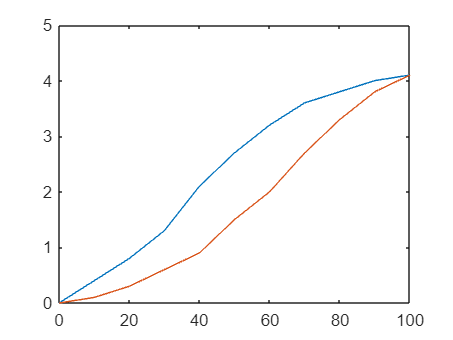


%Part A: 
plot(input, output_increment, input, output_decrement);


hysteresis_error = output_increment - output_decrement %HE

hysteresis_error =          0    0.3000    0.5000    0.7000    1.2000    1.2000    1.2000    0.9000    0.5000    0.2000         0


max_Output = max(output_decrement)

max_Output = 4.1000

HE_FS = (hysteresis_error / max_Output)*100 %Hysteresis error

HE_FS =          0    7.3171   12.1951   17.0732   29.2683   29.2683   29.2683   21.9512   12.1951    4.8780         0


max_HE = max(HE_FS) %maximum HE

max_HE = 29.2683

P4

k = 50

k = 50

T = 30

T = 30


syms s t
F(t) = (10*k)/((T*s+1)^2)

$$F(t) = \frac{500}{{\left(30\,s+1\right)}^{2}}$$

Ft(t) = (10*k*t )/(T^2) * exp(-t/T)

$$Ft(t) = \frac{5\,t\,{\mathrm{e}}^{-\frac{t}{30}}}{9}$$


ilaplace(F,s,t);
t_max = 30;
Ft_max = double (Ft(t_max))

Ft_max = 6.1313


time = linspace(0, 50 , 100)

time =          0    0.5051    1.0101    1.5152    2.0202    2.5253    3.0303    3.5354    4.0404    4.5455    5.0505    5.5556    6.0606    6.5657    7.0707    7.5758    8.0808    8.5859    9.0909    9.5960   10.1010   10.6061   11.1111   11.6162   12.1212   12.6263   13.1313   13.6364   14.1414   14.6465   15.1515   15.6566   16.1616   16.6667   17.1717   17.6768   18.1818   18.6869   19.1919   19.6970   20.2020   20.7071   21.2121   21.7172   22.2222   22.7273   23.2323   23.7374   24.2424   24.7475


y_t = double(Ft(time))

y_t =          0    0.2759    0.5426    0.8003    1.0492    1.2897    1.5218    1.7457    1.9618    2.1702    2.3711    2.5647    2.7511    2.9306    3.1034    3.2695    3.4293    3.5828    3.7302    3.8717    4.0074    4.1375    4.2622    4.3816    4.4957    4.6049    4.7091    4.8086    4.9035    4.9938    5.0798    5.1615    5.2390    5.3125    5.3821    5.4479    5.5101    5.5686    5.6236    5.6752    5.7236    5.7687    5.8108    5.8498    5.8859    5.9192    5.9497    5.9776    6.0029    6.0256


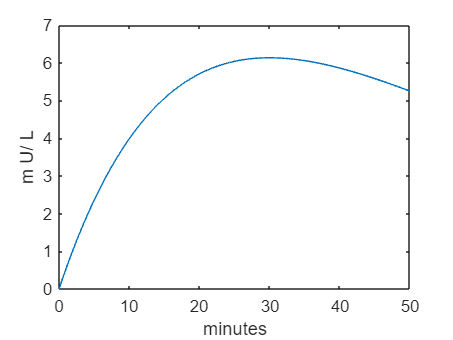

plot(time, y_t)
xlabel('minutes') 
ylabel('m U/ L') 


%last part u = 1U
syms s t
Ft(t) = (1*k*t )/(T^2) * exp(-t/T)

$$Ft(t) = \frac{t\,{\mathrm{e}}^{-\frac{t}{30}}}{18}$$

time = linspace(0, 10, 50)

time =          0    0.2041    0.4082    0.6122    0.8163    1.0204    1.2245    1.4286    1.6327    1.8367    2.0408    2.2449    2.4490    2.6531    2.8571    3.0612    3.2653    3.4694    3.6735    3.8776    4.0816    4.2857    4.4898    4.6939    4.8980    5.1020    5.3061    5.5102    5.7143    5.9184    6.1224    6.3265    6.5306    6.7347    6.9388    7.1429    7.3469    7.5510    7.7551    7.9592    8.1633    8.3673    8.5714    8.7755    8.9796    9.1837    9.3878    9.5918    9.7959   10.0000


y_t = double(Ft(time))

y_t =          0    0.0113    0.0224    0.0333    0.0441    0.0548    0.0653    0.0757    0.0859    0.0960    0.1059    0.1157    0.1254    0.1349    0.1443    0.1536    0.1627    0.1717    0.1806    0.1893    0.1979    0.2064    0.2148    0.2230    0.2311    0.2391    0.2470    0.2548    0.2624    0.2699    0.2773    0.2846    0.2918    0.2989    0.3059    0.3127    0.3195    0.3262    0.3327    0.3391    0.3455    0.3517    0.3578    0.3639    0.3698    0.3757    0.3814    0.3871    0.3926    0.3981


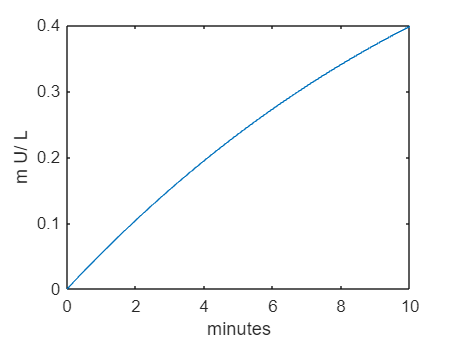

plot(time, y_t)
xlabel('minutes') 
ylabel('m U/ L') 